## **Pendolo smorzato**

Per verificare i risultati ottenuti analiticamente sfruttiamo il pacchetto Symbolic Toolbox di MATLAB, andiamo a definire i parametri simbolici dei quali avremo bisogno:

syms m l g theta(t) b;

Fatto ciò possiamo trattare questi elementi come se fossero dei parametri, in particolare l'ultimo "theta(t)" è una funzione, che contiene la dipendenza dalla variabile "t". Scriviamo ora l'energia **cinetica** e **potenziale**, e infine calcoliamo la Lagrangiana:

T = 1/2*m*l^2*diff(theta(t),t)^2

V = m*g*l*(1-cos(theta(t)))

L = T-V

Andiamo ora a svolgere i calcoli per scrivere l'equazione di Eulero-Lagrange:

primo_termine = diff(L,diff(theta(t),t));

secondo_termine = diff(L,theta(t));

eq_Eulero_Lagrange_ = diff(primo_termine,t)-secondo_termine == -b*diff(theta(t),t)

 Per integrare il sistema cominciamo a defnire i parametri per una prima risoluzione:

m = 5 ;%kg
b = 0.6; %kg/s
l = 1; %m

Scegliamo ora l'intervallo di integrazione del tempo:

dt = [0:0.05:40]; %#ok<NBRAK> 

Inseriamo ora le condizioni iniziali del sistema, per questo primo esempio prendiamo la velocità nulla e lo spostamento iniziale di un piccolo angolo:

x0 = [pi/10,0];

Per concludere, impostiamo i parametri di tolleranza dell'algoritmo ode45:

opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

Possiamo finalmente chiamare il risolutore ode45 con la seguente sinassi:

[t,x] = ode45(@(t,x)pendolo_smorzato(m,l,b,x,t),dt,x0,opts);	

Quello che ci viene restituito sono due grandezze, un vettore contenente gli istanti per i quali è stata calcolata la soluzione, e una matrice x che contiene per ogni istante di tempo il valore di x(1) e x(2), ossia theta e omega. 				

Andiamo a graficare il risultato: 			

figure;
plot(t,x(:,1),'k-',t,x( :,2),'r--');
grid;
title ('Andamento delle variabili di stato','FontSize',25);
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14)
legend('$\theta\,[rad]$','$\dot{\theta} [rad/s]$','Interpreter','latex');
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',18);

Aggiorniamo ora le condizioni iniziali per vedere il risultato da un diverso stato iniziale:

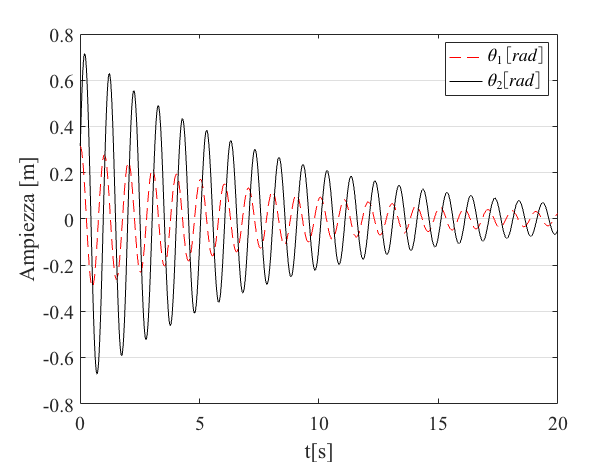

x0_2 = [pi/10,2];
[t,x2]  = ode45(@(t,x)pendolo_smorzato(m,l,b,x,t),dt,x0_2,opts);
figure;
plot(t,x(:,1),'r--',t,x2(:,1),'k-');
legend ('$\theta_1\,[rad]$','$\theta_2 [rad]$','Interpreter','latex');
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14)
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',18);

Se invece di modificare la velocità iniziale modifichiamo l'angolo di partenza lasciando la velocità uguale a zero otteniamo:

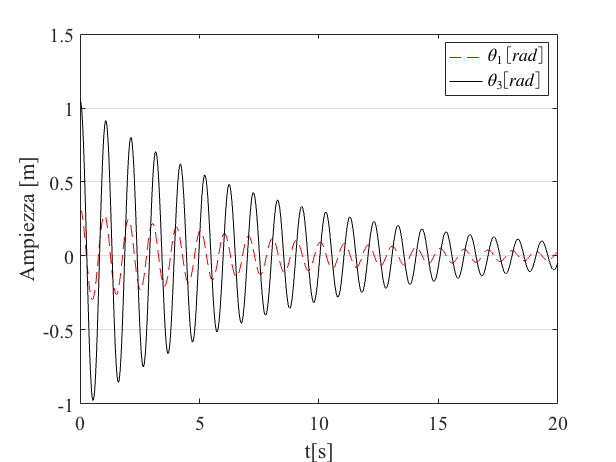

x0_3 = [pi/3,0];
[t,x3]  = ode45(@(t,x)pendolo_smorzato(m,l,b,x,t),dt,x0_3,opts);
figure;
plot(t,x(:,1),'r--',t,x3(:,1),'k-');
legend ('$\theta_1\,[rad]$','$\theta_3 [rad]$','Interpreter','latex');
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14)
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',18);

### Studio Parametrico

Andiamo ora a modificare alcuni parametri impostati all'inizio dello studio per vedere come cambia la risposta del sistema.

l_2 = 10;%m

Avendo aggiornato il valore di l, rendendolo 10 volte più grande, andiamo a risolvere il sistema con le condizioni iniziali scelte all'inizio:

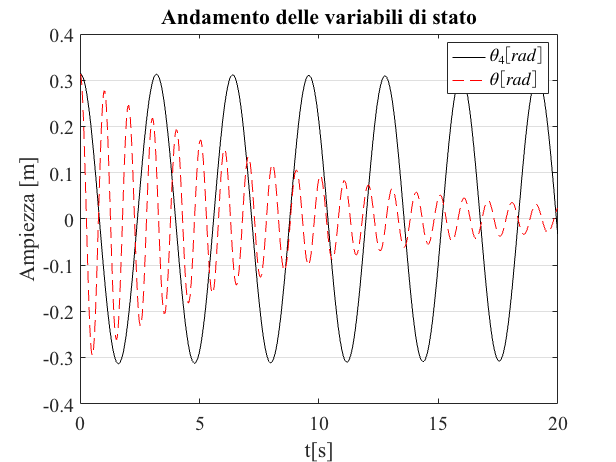

[t,x_4] = ode45(@(t,x)pendolo_smorzato(m,l_2,b,x,t),dt,x0,opts);	
figure;
plot(t,x_4(:,1),'k-',t,x(:,1),'r--');
title ('Andamento delle variabili di stato','FontSize',25);
legend('$\theta_4  [rad]$','$\theta [rad]$','Interpreter','latex');
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14);
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',18);

Modificando ora invece di L, la grandezza m, proviamo a vedere la rispsota:

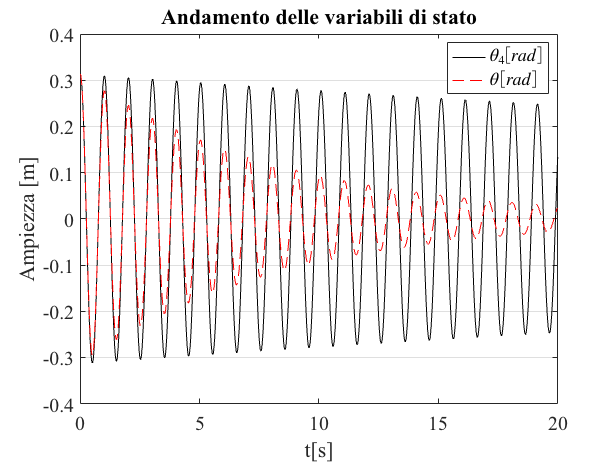

m_2 = 50;
[t,x_5] = ode45(@(t,x)pendolo_smorzato(m_2,l,b,x,t),dt,x0,opts);
plot(t,x_5(:,1),'k-',t,x(:,1),'r--');
title ('Andamento delle variabili di stato','FontSize',25);
legend('$\theta_4  [rad]$','$\theta [rad]$','Interpreter','latex');
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14);
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',18);

Variamo invece di L ed m, la grandezza b:

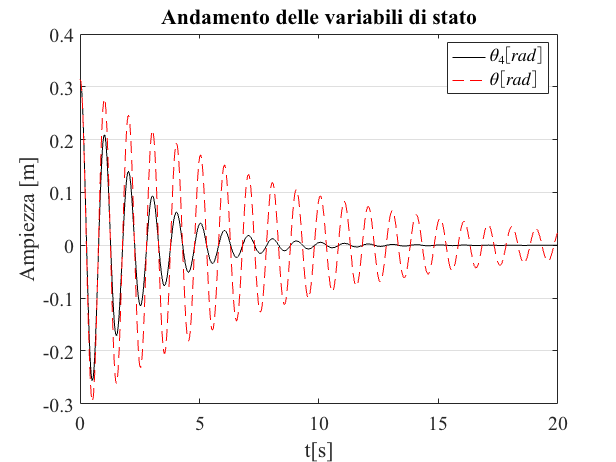

b_2 = 2;%kg/s
[t,x_6] = ode45(@(t,x)pendolo_smorzato(m,l,b_2,x,t),dt,x0,opts);
plot(t,x_6(:,1),'k-',t,x(:,1),'r--');
title ('Andamento delle variabili di stato','FontSize',25);
legend('$\theta_4  [rad]$','$\theta [rad]$','Interpreter','latex');
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14);
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',18);

###  Flusso e spazio delle fasi

Andiamo ora a studiare lo spazio delle fasi, ciè il grafico che ha per assi tehta e theta punto.

dt_f = [0:0.05:80]; %#ok<NBRAK> 
[t,x_f] = ode45(@(t,x)pendolo_smorzato(m,l,b,x,t),dt_f,x0,opts);
figure;
plot(x_f(:,1),x_f(:,2),'b-');
grid;
title('Spazio delle fasi','FontSize',25);
xlabel('$\theta$[rad]','Interpreter','latex');
ylabel('$\dot{\theta}[rad/s]$','Interpreter','latex');
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',18);
axis auto;

Andiamo ora a graficare il "ritratto di fase" come campo vettoriale:

[X,Y] = meshgrid(-0.4:0.05:0.4,-1.5:0.2:1.5);
dXdt = Y;
dYdt = -(b/(m*(l)^2))*Y-g/l*sin(X);
figure;
quiver(X,Y,dXdt,dYdt,1);

Se ci aggiungiamo sopra la traiettoria compiuta dal nostro sistema:

hold on;
plot(x_f(:,1),x_f(:,2),'r-');
xlabel('$\theta$[rad]','Interpreter','latex');
ylabel('$\dot{\theta}[rad/s]$','Interpreter','latex');
grid on;

### Studio delle condizioni iniziali

Da ora in avanti si lavorerà con un pendolo che non è più smorzato, andiamo a ricavare l'equazione del modo.

Avremo bisogno di una nuova function, che si chiamerà "pendolo lineare" senza il termine di smorzamento, utilizzeremo gli stessi parametri iniziali, andiamo a integrare il pendolo:

[t,x_lin] = ode45(@(t,x)pendolo_lineare(t,x,m,l),dt,x0,opts);	

Andiamo ora a graficare le coordinate x(t) e y(t):

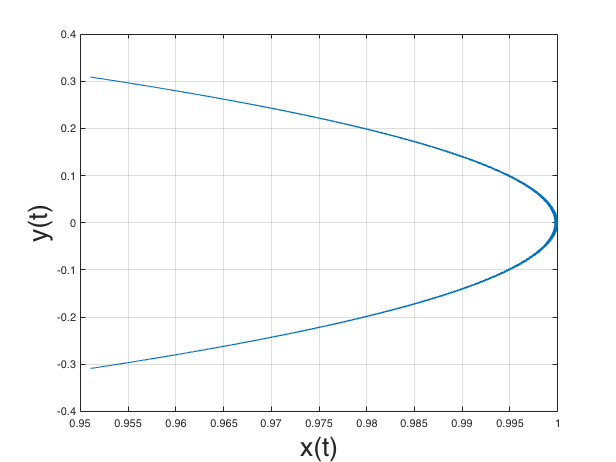

cord_x_lin = cos(x_lin(:,1))*l;
cord_y_lin = sin(x_lin(:,1))*l;
figure;
plot(cord_x_lin,cord_y_lin);
xlabel('x(t)','FontSize',24);
ylabel('y(t)','FontSize',24);
grid on;

Modificando le condizioni iniziali:

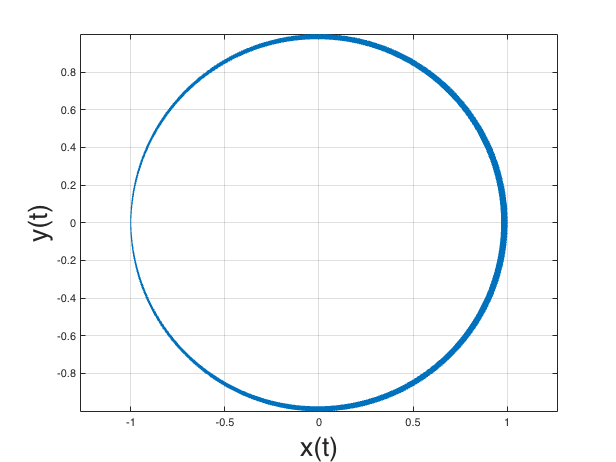

x0_lin = [pi,0];
[t,x_lin] = ode45(@(t,x)pendolo_lineare(t,x,m,l),dt,x0_lin,opts);
cord_x_lin = cos(x_lin(:,1))*l;
cord_y_lin = sin(x_lin(:,1))*l;
figure;
plot(cord_x_lin,cord_y_lin);
axis equal;
xlabel('x(t)','FontSize',24);
ylabel('y(t)','FontSize',24);
grid on;

Oppure ancora:

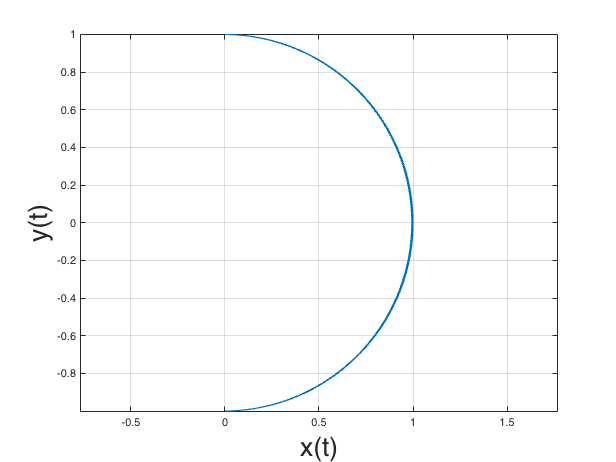

x0_lin = [pi/2,0];
[t,x_lin] = ode45(@(t,x)pendolo_lineare(t,x,m,l),dt,x0_lin,opts);
cord_x_lin = cos(x_lin(:,1))*l;
cord_y_lin = sin(x_lin(:,1))*l;
figure;
plot(cord_x_lin,cord_y_lin);
axis equal;
xlabel('x(t)','FontSize',24);
ylabel('y(t)','FontSize',24);
grid on;